# BME3053C Final Project - Eczema Detection 

Authors: Megan Yip, Isha Verma

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

email: iverma@ufl.edu, megan.yip@ufl.edu

Updated April 22nd, 2021

clc; clear;

## Welcome to the Eczema Detection Program!

This program will help you determine what type of eczema or skin condition you may have.

Based on your answers to the following questions, we will tell you what type of eczema you most likely have and offer suggestions for treatment. Please be sure to consult a medical professional before starting any sort of treatment. 

Instructions: Select Yes or No for each of the following questions. Once a diagnosis is stated, do not continue selecting answers. After a diagnosis is gievn, more infomration can be found in section 5.

### Section 1

Your diagnosis is nummular/discoid dermatitis. 
 Go to section 5 to learn more about symptoms and treatment!

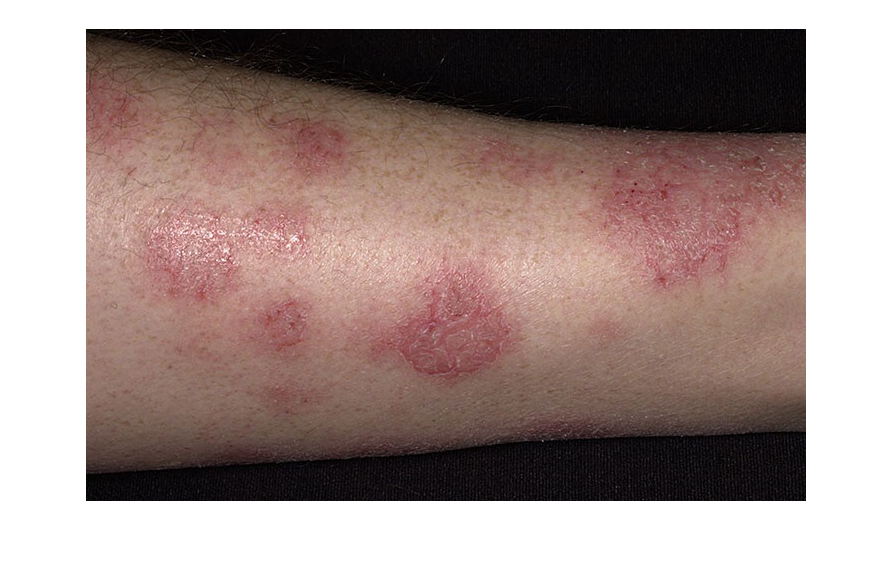

diag = "num"

neuro = imread('Neuro.jpg');
stasis = imread('stasis.jpg');
atopic = imread('atopic.jpg');
contact = imread('contact.jpg');
seb = imread('seb.jpg');
dys = imread('dys.jpg');
num= imread('num.jpg');

diag = "";
A = "Y";
if A== 'Y'
    B = "Y";
    if B== 'Y'
        fprintf('Your diagnosis is nummular/discoid dermatitis. \n Go to section 5 to learn more about symptoms and treatment!')
        figure(1)
        imshow(num)
        diag = "num";
    elseif B=='N'
        C = "Select";
        if C== 'Y'
            fprintf('Your diagnosis is dyshidrotic dermatitis or possibly contact dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
            
            figure(2)
            subplot(121)
            imshow(dys)
            title('Dyshidrotic Dermatitis')
            
            hold on;
            
            subplot(122)
            imshow(contact)
            title('Contact Dermatitis')
            
            hold off;
            
            diag = "dys";
        end
    end
end

### Section 2

fprintf('Please skip this section if you have already received a potential diagnosis.');

Please skip this section if you have already received a potential diagnosis.

if diag ==""
    D = "Select";
    if D=='Y'
        E = "Select";
        if E == 'Y'
            fprintf('Your diagnosis is sebhorreic dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
            figure(10)
            imshow(seb)
            diag = "seb";
        end
    end
    
end


### Section 3

    fprintf('Please skip this section if you have already received a potential diagnosis.')    

Please skip this section if you have already received a potential diagnosis.

    if diag =="" 
        F= "Select";
        if F == 'Y'
            G = "Select";
            if G == 'Y'
                H = "Select";
                if H== 'Y'
                    fprintf('Your diagnosis is stasis dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
                    figure(4)
                    imshow(stasis)
                    diag = "stasis";
                end
            elseif G == 'N'                                    
                figure(5)
                subplot(141)
                imshow(stasis)
                title('AA')
                
                hold on;
    
                subplot(142)
                imshow(neuro)
                title('BB');
                
                hold on;
    
                subplot(143)
                imshow(atopic)
                title('CC')
                
                hold on;
    
                subplot(144)
                imshow(contact)
                title('DD')
                
                hold off;
                   
                    I= "Select";
                                        
                    if I == 'AA'
                        fprintf('Your diagnosis is stasis dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
                        figure(6)
                        imshow(stasis)
                        diag = "stasis";
                    elseif I == 'BB'
                        fprintf('Your diagnosis is neurodermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
                        figure(7)
                        imshow(neuro)
                        diag = "neuro";
                    end 
            end
        end
        
    end

   

### Section 4

    fprintf('Please skip this section if you have already received a potential diagnosis.')    

Please skip this section if you have already received a potential diagnosis.

    if diag == ""
        J = "Select";
        
        if J == 'Y'
            fprintf('Your diagnosis is contact dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
            figure (8)
            imshow(contact)
            diag = "contact";
        elseif J== 'N'
            fprintf('Your diagnosis is atopic dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
            figure(9)
            imshow(atopic)
            diag = "atopic";

        end
        
    end

%added an alternate case if we were unable to diagnose
if diag == ""
   fprintf("") 
end


### Section 5

%add in function here with diseases and what to do
treat = furtherSteps(diag);
fprintf(treat);

Potential diagnosis: Nummular Eczema 

Common Locations: arms, legs, torso, hands 

Signs and symptoms: 
     coin shaped lesions/paches 

Description: Nummular eczema is when you have circular, itchy patches on your skin. It is also known as discoid 
     eczema and nummular dermatitis. It can be triggered by dry skin and insect bites, scrapes, chemical burns. 
     Nummular eczema can often be secondary to another type of eczema, such as stasis eczema if it is present on your legs.  

Treatment: To confirm that it is nummular eczema, doctors will often scrape the skin. Treatment involves 
     corticosteroids and antibiotics prescribed by a healthcare professional. 
Similar conditions: ringworm 

Source: https://nationaleczema.org/eczema/types-of-eczema/nummular-eczema/

fprintf(' \n \n')

choice = "Select";
moreInfo = furtherSteps(choice);
fprintf(moreInfo);

### Section 6

fprintf('If you were diagnosed with nummular or atopic eczema, you may choose to upload an image of your eczema to gauge its severity. \n For highest accuracy, we ask that you upload a clear photo no larger than 1000x1000 pixels');

If you were diagnosed with nummular or atopic eczema, you may choose to upload an image of your eczema to gauge its severity. 
 For highest accuracy, we ask that you upload a clear photo no larger than 1000x1000 pixels

pic = 'num3.jpg';
accuracyC = 0;
if pic ~= "" %checks to see if the user has entered text
    if diag ~= 'atopic' && diag ~= 'num' %checks to see if it is within the appropriate size
        pic = "";
        accuracyC = 1;
        fprintf("Currently our program does not support redness checking for your type of dermatitis. Please see a physician to gauge severity");
    else
        str = pic(1, 1);
        len = length(str);
        start = length(pic) - 4;
        ending = length(pic);
        if pic(start:end) ~= ".jpg"  && pic( (start - 1):end) ~= ".jpeg"
            fprintf("Please enter a file name ending with .jpg or .jpeg");
        end
    end
end

Please enter a file name ending with .jpg or .jpeg

Thank you for your image submission. We will now begin processing.


Please select a region of interest and create your mask by right clicking the region.

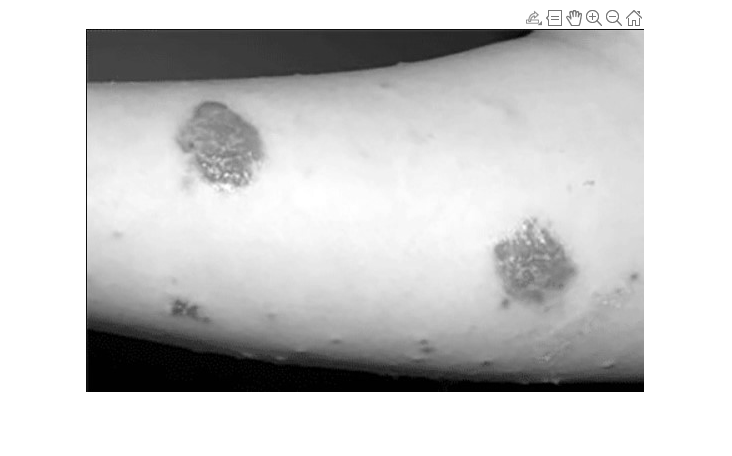


The average rednesss in your region is 154.121381 out of a maximum of 255

if accuracyC == 0
   fprintf("Thank you for your image submission. We will now begin processing.")
   [rows, cols, colors] = size(pic);
   if rows > 1000 || cols > 1000
       fprintf('Your image has %f and %f columns. This image may be too large for us to process quickly. \n If you would like, you may change the image. If not, we will proceed with this one.', rows, cols);
   end
   img = imread(pic);
   img = img(:, :, 2);
   fprintf('\nPlease select a region of interest and create your mask by right clicking the region.');
   section = roipoly(img);
   red_vals = img(section);
   red_sum = sum(red_vals, 1);
   red_mean = sum(red_vals, 1) / sum(red_vals~=0, 1);
   fprintf('\nThe average rednesss in your region is %f out of a maximum of 255', red_mean);
end